# Модель толкателя

syms F(t);
F(t)=(heaviside(t)-heaviside(t-0.2))*50*(1-cos(4*pi*2.5*t))

$$F(t) = \left(50\,\mathrm{heaviside}\left(t-\frac{1}{5}\right)-50\,\mathrm{heaviside}\left(t\right)\right)\,\left(\cos\left(10\,\pi \,t\right)-1\right)$$

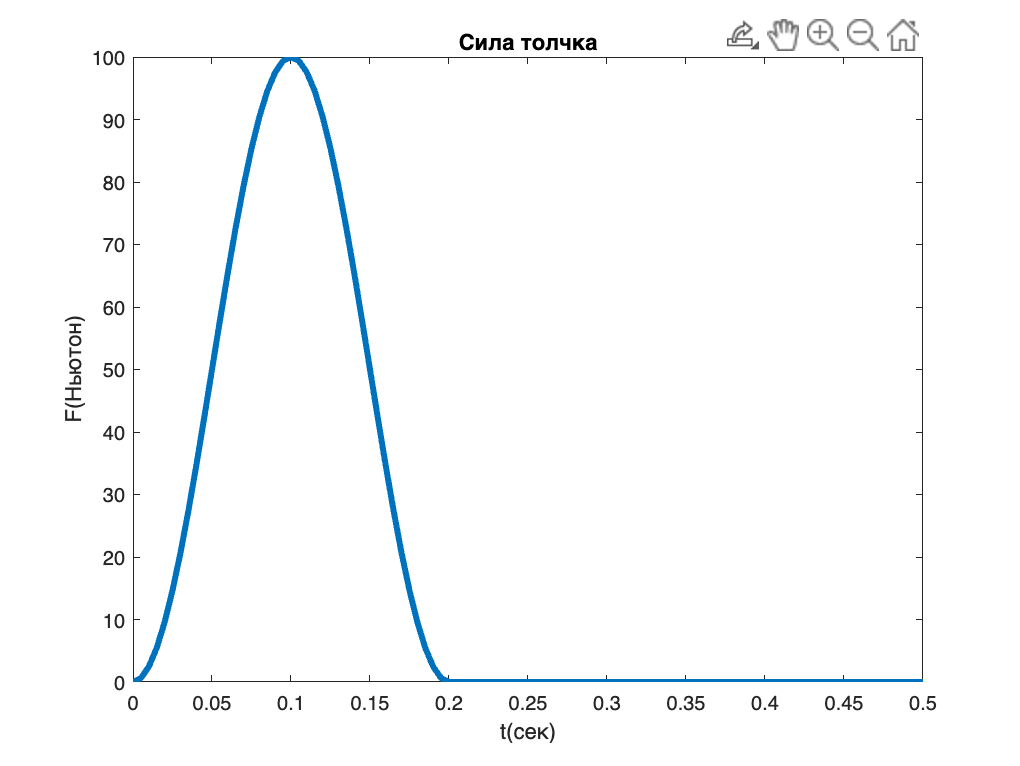

t=0:0.005:0.5;
plot(t,F(t),'LineWidth',3);title("Сила толчка");xlabel('t(сек)');ylabel("F(Ньютон)")

# Поиск p и c

m=74; g=9.81;l=0.88;
J=4/3*m*l^2;%момент инерции тела
syms p c
b=0.6;
p=double(solve(p/J==2*b,p,'Real',true))

p = 91.6890

c=double(solve((c-m*g*l)/J==(2*pi*0.3)^2+b^2,c,'Real',true))

c = 937.8140

# Уравнение движения

## 
$$\[
J\ddot{\theta}=mgl\theta+M-Fl
\]
\[
J\ddot{\theta}=mgl\theta-C\theta-P\dot\theta-Fl
\]
\[
J\ddot{\theta}+P\dot\theta+\theta(C-mgl)+Fl=0
\]

\[
\ddot{\theta}+\frac{P}{J}\dot\theta+\theta\frac{(C-mgl)}{J}+\frac{Fl}{J}=0
\]
$$


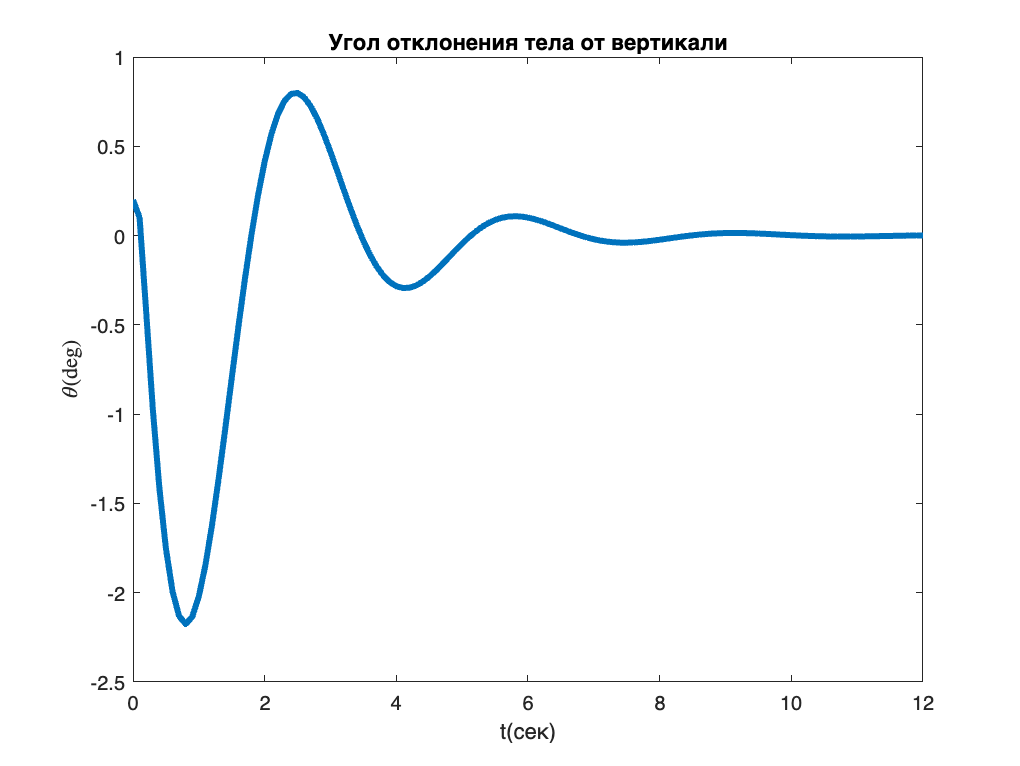

syms y(t);
Dy = diff(y,t);
cond = [y(0)==deg2rad(0.2), Dy(0)==0];
eqn = diff(y,t,2)+p/J*diff(y,t)+(c-m*g*l)*y/J+F(t)*l/J==0;
ySol(t) = dsolve(eqn,cond);
t=0:0.1:12;
plot(t,rad2deg(ySol(t)),'LineWidth',3);
title("Угол отклонения тела от вертикали");
xlabel("t(сек)");ylabel('$\theta$(deg)','Interpreter','latex')

# Сагиттальное движение центра масс

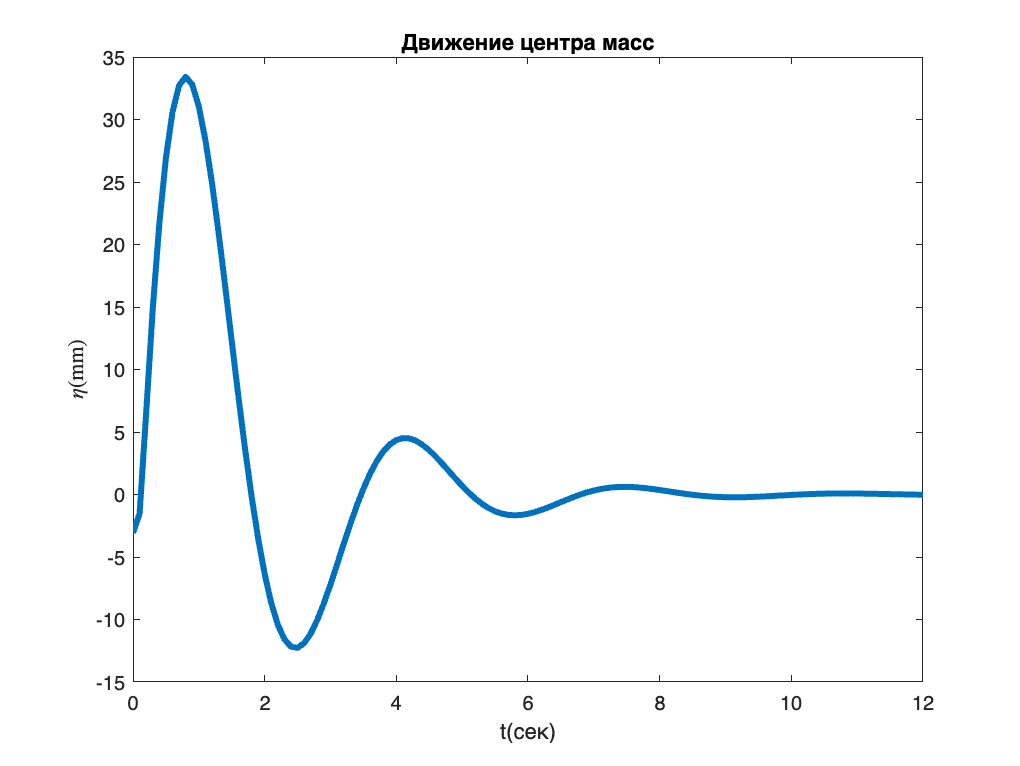

plot(t,-l*ySol(t)*1000,'LineWidth',3);
title("Движение центра масс");
xlabel("t(сек)");ylabel('$\eta$(mm)','Interpreter','latex')